# Welding poses

Team: Ana Siesto Pérez and Xavier Marti Llull G11-A

Link: [https://drive.matlab.com/sharing/55d1bc1a-b78d-4e10-bd72-1c04301e22ce](https://drive.matlab.com/sharing/55d1bc1a-b78d-4e10-bd72-1c04301e22ce) 

A Unimation Puma 560 robot is used to weld a folded tubes frame as it is shown in the next figures.

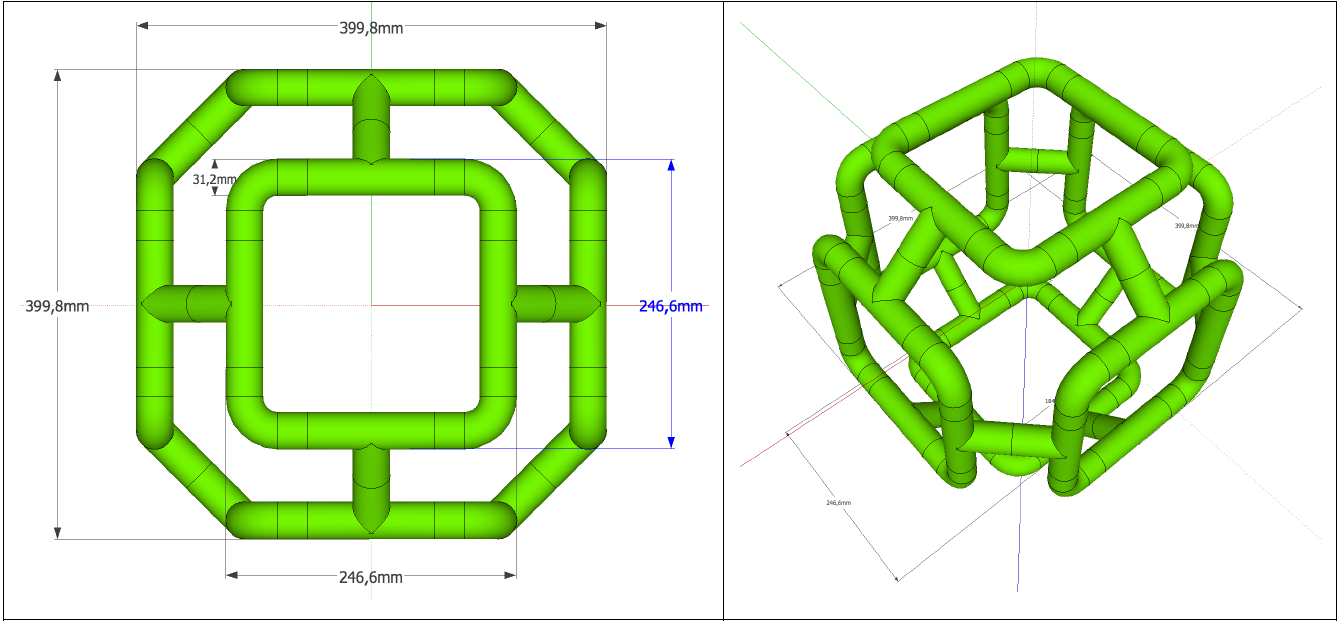

The task for the Puma 560 consists in welding the six folded squared tube among them with 32 points. The welding trajectory can be assumed to as two orthogonal and intersecting cylinders with radius 𝑟 = 15.6mm. The trajectory to be followed by the welder can be parameterized as follows:


$$p(t) = \left[ {\begin{array}{*{20}{c}}
  {x(t)} \\ 
  {y(t)} \\ 
  {z(t)} 
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
  {r\cos (t)} \\ 
  {r\sin (t)} \\ 
  {\left[\kern-0.15em\left[ {r\cos (t)} 
 \right]\kern-0.15em\right]} 
\end{array}} \right];t \in \left[ {\begin{array}{*{20}{c}}
  0&{2\pi } 
\end{array}} \right]$$


## Read and plot the part

Download STLtools from Matlab: [https://es.mathworks.com/matlabcentral/fileexchange/51200-stltools](https://es.mathworks.com/matlabcentral/fileexchange/51200-stltools)

Add it to the path.

clear
[V,F, N,name]=stlRead('Folded_Tubes.stl');
clf
stlPlot(V,F,name)
alpha 0.4
axis equal
hold on

## Setting up dimensions

r=15.6; % Tube radius
t=0:pi/16:2*pi; % Scan variable
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))]% dot height

cp0 =    15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
         0    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000
   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
 

## Plotting

### Frame description

trplot(eye(4), 'length', 100,'arrow','width', 1 )

### Weld points 

At origen

scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
xyzlabel% RTB function

## Obtain the weld point coordinates of two tubes

Get familiar with the following RTB functions:

help on: transl, trotx, troty, trotz

I'am solving for you two tubes welding at origen as an example.

### Load cylinder/tube info

Get familiar with the variable: V_Cylinder

figure
load('Vertices_Faces_Cylinder.mat')

### Plotting tube

First reshape the Cylinder vertices: radius 15.6 and height 50

V_Cylinder=[15.6*V_Cylinder(:,1:2) 50*V_Cylinder(:,3)] 

V_Cylinder =    15.6000         0         0
   15.6000         0   50.0000
   14.8365    4.8207         0
   14.8365    4.8207   50.0000
   12.6207    9.1694         0
   12.6207    9.1694   50.0000
    9.1694   12.6207         0
    9.1694   12.6207   50.0000
    4.8207   14.8365         0
    4.8207   14.8365   50.0000


Plot it

patch('Vertices',V_Cylinder,'Faces',F_Cylinder,'facecolor',[0.5 0.8 0.8],'facealpha',0.8); 
xyzlabel
view(3)
hold on

### Another tube

V2_Cylinder=troty(pi/2)*transl(0,0,-25)*[V_Cylinder' ;ones(1,length(V_Cylinder))]

V2_Cylinder =   -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000  -25.0000   25.0000
         0         0    4.8207    4.8207    9.1694    9.1694   12.6207   12.6207   14.8365   14.8365   15.6000   15.6000   14.8365   14.8365   12.6207   12.6207    9.1694    9.1694    4.8207    4.8207    0.0000    0.0000   -4.8207   -4.8207   -9.1694   -9.1694  -12.6207  -12.6207  -14.8365  -14.8365  -15.6000  -15.6000  -14.8365  -14.8365  -12.6207  -12.6207   -9.1694   -9.1694   -4.8207   -4.8207         0         0
  -15.6000  -15.6000  -14.8365  -14.8365  -12.6207  -12.6207   -9.1694   -9.1694   -4.8207   -4.8207   -0.0000   -0.0000    4.8207    4.8207    

patch('Vertices',V2_Cylinder(1:3,:)','Faces',F_Cylinder,'facecolor',[0.5 0.8 0.8],'facealpha',0.8); 
axis equal

Visualize the 32 welding points

scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
hold on

Visualize the frame wrt are drawn

trplot(eye(4), 'length', 100,'arrow','width', 1 )

## All weldding points

The final graphical result must be: (doble click on: 32x24_Welding_Points_Solution.fig ) in case the 'open' command do not work!

Add reference frame for all cloud weld points.

Obtain a vector with all weldding points, i.e the six folded squared. Take advantage of the figure symetry.

Notice that there is small misalignement due to incorrect 'stl' file.

open('32x24_Welding_Points_Solution.fig')
alpha 0.3
[V,F, N,name]=stlRead('Folded_Tubes.stl');
stlPlot(V,F,name)
xyzlabel
alpha 0.4
axis equal
hold on
cp=[cp0 ...
    transl(0,-184.3,-107.7)*trotx(-135*pi/180)*cp0 ...              % We apply the appropiate rotations and translations to cp0 cylinder
    transl(0,184.3,-107.7)*trotx(135*pi/180)*cp0 ...                % All translations have been aplied taking into account the radius of our tubes and the measurements at top of the document
    transl(-184.3,0,-107.7)*troty(135*pi/180)*trotz(pi/2)*cp0 ...
    transl(184.3,0,-107.7)*troty(-135*pi/180)*trotz(pi/2)*cp0 ...
    transl(0,-184.3,107.7)*trotx(-45*pi/180)*cp0 ...
    transl(0,184.3,107.7)*trotx(45*pi/180)*cp0 ...
    transl(-184.3,0,107.7)*troty(45*pi/180)*trotz(pi/2)*cp0 ...
    transl(184.3,0,107.7)*troty(-45*pi/180)*trotz(pi/2)*cp0 ...
    transl(-184.3,107.7,0)*trotz(45*pi/180)*troty(pi/2)*cp0 ...
    transl(-184.3,-107.7,0)*trotz(-45*pi/180)*troty(pi/2)*cp0 ...
    transl(184.3,107.7,0)*trotz(-45*pi/180)*troty(-pi/2)*cp0 ...
    transl(184.3,-107.7,0)*trotz(45*pi/180)*troty(-pi/2)*cp0 ...
    transl(-107.7,184.3,0)*trotz(45*pi/180)*troty(-pi/2)*cp0 ...
    transl(107.7,184.3,0)*trotz(-45*pi/180)*troty(pi/2)*cp0 ...
    transl(-107.7,-184.3,0)*trotz(-45*pi/180)*troty(-pi/2)*cp0 ...
    transl(107.7,-184.3,0)*trotz(45*pi/180)*troty(pi/2)*cp0 ...
    transl(0,-107.7,184.3)*trotx(135*pi/180)*cp0 ...
    transl(0,107.7,184.3)*trotx(-135*pi/180)*cp0 ...
    transl(107.7,0,184.3)*troty(135*pi/180)*trotz(pi/2)*cp0 ...
    transl(-107.7,0,184.3)*troty(-135*pi/180)*trotz(pi/2)*cp0 ...
    transl(0,-107.7,-184.3)*trotx(45*pi/180)*cp0 ...
    transl(0,107.7,-184.3)*trotx(-45*pi/180)*cp0 ...
    transl(107.7,0,-184.3)*troty(45*pi/180)*trotz(pi/2)*cp0 ...
    transl(-107.7,0,-184.3)*troty(-45*pi/180)*trotz(pi/2)*cp0]

scatter3(cp(1,:),cp(2,:),cp(3,:),'r','LineWidth',2)
R_BA=roty(135*pi/180)*rotz(pi/2)
T_BA=[R_BA [107.7 0 184.3]';[0 0 0 1]]
trplot(T_BA, 'length', 100,'arrow','width', 1)                      % We add an example of reference frame